clear all;

Инициализация задачи

lambda = -3; mu = 1.5;
F= @(t,y) lambda*y;    G = @(t,y) mu*y;
%sde = @(t,y) F(t,y)dt + G(t,y)dW;

Начальные условия

%randn("state",100);
rng("default");
t_0 = 0;
Yzero = 1;
h = 2^(-2);
rightBorder = 2;
dW = sqrt(h)*randn(1,(rightBorder-t_0)/h);
W = [0 cumsum(dW)];

"Точное решение"

Ytrue = Yzero*exp((F(0,Yzero) - 0.5*G(0,Yzero)^2)*(0:h:rightBorder) + G(0,Yzero)*W);
hold on
plot ([0:h:rightBorder], Ytrue, '-m');

Решение численными методами

tic
[T,Y] = EulerMaruyama(F, G, h,t_0, Yzero, rightBorder);
toc

Elapsed time is 0.034507 seconds.


[T1,Y1] = RKCforSDE(F, G, h, t_0, Yzero, rightBorder, 2, 0.25);
toc

Elapsed time is 0.071164 seconds.


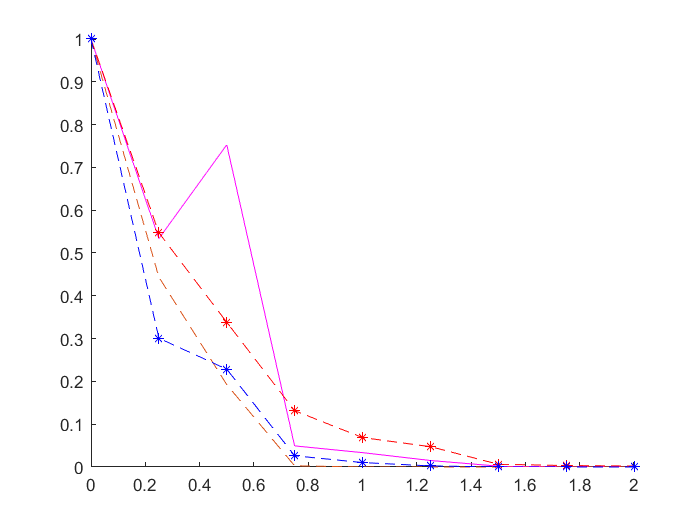

[T2, Y2] = Milstein(F, G, h, t_0, Yzero, rightBorder);
plot (T,Y, '--');
plot (T1,Y1, 'r--*');
plot (T2,Y2, 'b--*');
hold off

%plot (T2, Y2, "--o");

Средние квадраты

numExp = 200;
rightBorder = 50; 
h = h*2

h = 0.5000

tic
for i=1:numExp
    [Tem, EM(i,:)] = EulerMaruyama(F, G, h, t_0, Yzero, rightBorder);
end

for i=1:length(Tem)
    meanY(i) = mean(EM(:,i).^2);
end
toc

Elapsed time is 2.312169 seconds.


%%////////////
for i=1:numExp
    [Trock, Rock(i,:)] = RKCforSDE(F, G, h, t_0, Yzero, rightBorder, 2, 0.25);
end

for i=1:length(Trock)
    meanYrock(i) = mean(Rock(:,i).^2);
end
toc

Elapsed time is 4.616092 seconds.


%%///////////
h = h*2

h = 1

for i=1:numExp
    [hTem, hEM(i,:)] = EulerMaruyama(F, G, h, t_0, Yzero, rightBorder);
end

for i=1:length(hTem)
    meanhY(i) = mean(hEM(:,i).^2);
end
toc

Elapsed time is 6.882765 seconds.


%%/////////
for i=1:numExp
    [hTrock, hRock(i,:)] = RKCforSDE(F, G, h, t_0, Yzero, rightBorder, 2, 0.25);
end

for i=1:length(hTrock)
    meanhYrock(i) = mean(hRock(:,i).^2);
end
toc

Elapsed time is 9.146446 seconds.


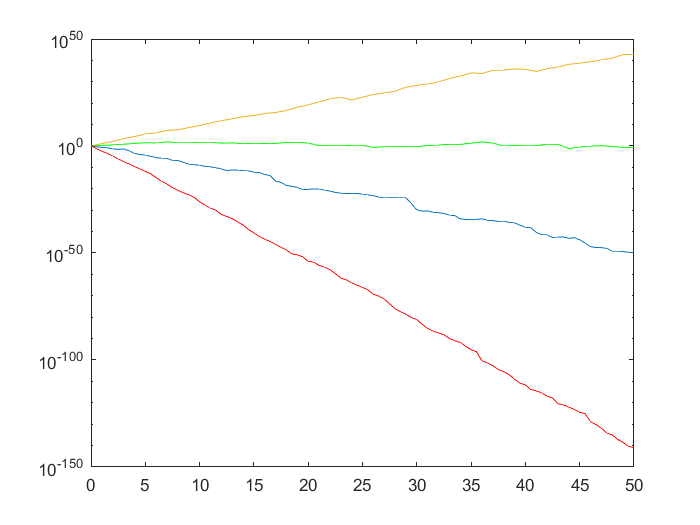

%%///////
figure
semilogy(Tem, meanY, Trock,meanYrock, 'r', hTem, meanhY, hTrock,meanhYrock, 'g');
hold on